% define the number of agents
N = 5;

% define the maximum X
xMax = 20;

% length of one time step
dt = 0.01;

% how long the simulation will run
T = 10;

% initialise the position of each agent
agents = zeros(T/dt, N+1);
agents(:, 1) = dt:dt:T;
agents(1, 2:N+1) = randperm(xMax, N);
centroid = mean(agents(1, 2:N+1));

Laplacian for a single path

% --------------------------------
% define the adjacency matrix
A = [[0, 1, 0, 0, 0];
     [1, 0, 1, 0, 0];
     [0, 0, 0, 0, 1];
     [0, 1, 2, 0, 1];
     [0, 0, 3, 1, 0]];
% define the laplacian matrix


D = diag(sum(A,2));
L = D-A;

y = null(L');
y = y/sum(y)

y =     0.0455
    0.0455
    0.6818
    0.0455
    0.1818


in = sum(A, 2)';
out = sum(A, 1);
deg = in + out;
% --------------------------------

The Simulation

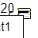

for t = 2*dt:dt:T
    idx = cast(t/dt, "uint32");
    agents(idx, 2:N+1) = update_agents(agents(idx-1, 2:N+1), dt, L);
end 

figure('Position', [0, 0, 500, 500]);
plot(agents(:, 1), agents(:, 2:N+1));
hold on
plot(agents(:, 1), agents(:, 2:N+1)*y, 'k--', 'LineWidth', 1.5);
legend('Agent1', 'Agent2', 'Agent3', 'Agent4', 'Agent5', 'Centroid')
set(gca,"XGrid","off","YGrid","on");
ylim(gca,[1,xMax]);